# ANÁLISIS ESTRUCTURAL INTEGRADO

El cálculo comienza al decidir cómo representar el objeto físico. Una varilla puede modelarse mediante su eje; una sección mediante su contorno; un conjunto de vigas mediante nodos y conexiones. Esa idealización determina qué deformaciones y esfuerzos puede describir la solución.

Este documento reúne las familias de cálculo de los dieciséis capítulos. Conserva toda la carpeta: los capítulos explican cada modelo y las funciones compartidas realizan las operaciones. No es necesario ejecutar los capítulos antes de usar este documento.

Se añaden comprobaciones estructurales de secciones generales, uniones simples, estabilidad local de placas y elasticidad estática de sólidos 3D. Se aplican a estructuras y componentes de cualquier sector dentro de las hipótesis indicadas. El número 0 en la columna Capitulo identifica una ampliación integrada; no exige otro Live Script. Solo el módulo de sólidos requiere PDE Toolbox.

## 1. Selección del análisis

Primero identifica qué necesitas conocer. ¿Alargamiento o giro de una barra? ¿Reacciones y desplazamientos de una estructura? ¿Tensiones en una sección? ¿Estabilidad, impacto o fatiga? La tabla relaciona cada necesidad con una clave de análisis. Elegir una clave no comprueba por sí solo que las hipótesis describan la pieza real.

carpetaAE=fileparts(mfilename('fullpath'));
if ~isempty(carpetaAE),addpath(carpetaAE);end
ae_verificar;
catalogo=ae_catalogo;
disp(catalogo);

             Clave                                      Necesidad                             Capitulo
    _______________________    ___________________________________________________________    ________

    "axial"                    "Alargamiento, temperatura y contacto de una barra"                1   
    "cercha"                   "Esfuerzos de barras unidas mediante articulaciones"               2   
    "seccion"                  "Área, centroide e inercias de una sección"                        3   
    "torsion"                  "Giro y tensiones de un eje recto"                                 4   
    "viga"                     "Flexión transversal de una viga plana"                            5   
    "flexion_oblicua"          "Tensiones por flexión biaxial o carga excéntrica"                 6   
    "sistema_barras"           "Esfuerzos y desplazamientos de un marco 2

seleccion="directa";
analisis="solido3d";

Selección directa: escribe una clave de la tabla. Selección guiada: cambia seleccion a "guiada" y completa las tres respuestas. Si la combinación admite varios modelos, el programa presenta las alternativas y pide precisar la selección; no elige una teoría de manera implícita.

seleccion="directa";
analisis="axial";
guia.objeto="barra_recta";
guia.accion="axial";
guia.interes="deformaciones";
ajustesGuia=struct;
if seleccion=="guiada"
    [analisis,orientacion,ajustesGuia]=ae_orientar(guia);disp(orientacion);
else
    assert(seleccion=="directa",'Seleccion: directa o guiada.');
end
assert(any(catalogo.Clave==analisis),'La clave no pertenece al catalogo.');
disp(ae_alcance(analisis));

Barra recta axial, E y F constantes por tramo, pequeñas deformaciones, cargas y temperatura lineales por tramo, apoyos bilaterales y hasta ocho topes unilaterales. No comprueba pandeo.


Respuestas admitidas: objeto = barra_recta, barras_articuladas, marco, seccion, punto, superficie_revolucion, barra_curva, plataforma, union_adhesiva, union o placa. accion = axial, torsion, flexion, combinada, temperatura, compresion, impacto, rotacion, ciclos, plastificacion, presion o geometria. interes = esfuerzos, deformaciones, resistencia, estabilidad o propiedades. marco + combinada + deformaciones conduce a sistema_barras; marco + combinada + resistencia propone resistencia_combinada, que requiere secciones circulares. seccion + combinada + resistencia conduce a seccion_general; union + axial + resistencia a uniones; placa + compresion + estabilidad a placa_local.

Para una pieza maciza puedes elegir objeto="solido", accion="combinada" e interes="resistencia". Esto selecciona solido3d; revisa primero las caras y unidades en su modo geometria antes de configurar el caso real.

## 2. Hipótesis y unidades

Antes de calcular, dibuja el sistema e identifica apoyos, direcciones de carga, geometría y material. Revisa el alcance mostrado arriba. La elasticidad lineal, la idealización de los apoyos y la aproximación de pequeños desplazamientos deben corresponder al caso. Los modos de plasticidad, estabilidad e impacto tienen sus propias hipótesis, indicadas en el alcance.

Una fuerza se mide en N; una tensión es fuerza por unidad de área y se mide en Pa. La deformación unitaria relaciona el cambio de longitud con la longitud inicial; no tiene unidades. El desplazamiento es el movimiento de un punto y se mide en m. E representa el módulo de Young y G el módulo de cortante. F designa el área de sección en los datos, siguiendo la notación utilizada en los capítulos.

Un grado de libertad es una componente de desplazamiento o giro. Un apoyo restringe algunas componentes y deja otras libres. Una articulación puede impedir traslaciones y permitir giros; un empotramiento impide las traslaciones y los giros que corresponden al modelo. Debes representar esas restricciones mediante la tabla de apoyos.

Usa m, N, Pa, rad, kg y s. Un área de 400 mm² se introduce como 400e-6 m²; 210 GPa como 210e9 Pa. Un cambio de temperatura de 20 °C equivale a 20 K. En matrices de apoyos, NaN significa dirección libre y 0 significa desplazamiento o giro impedido. Una fila de cargas corresponde a una posición o nodo, según el modelo.

En estática, el equilibrio exige que la resultante de fuerzas y la de momentos sean nulas. Para obtener deformaciones se añaden la ley constitutiva del material y las relaciones de compatibilidad. La memoria de cada familia desarrolla esas relaciones con los datos del caso.

## 3. Datos del caso

Conserva la identificación del cálculo junto a los resultados. La referencia de geometría puede ser un plano o archivo CAD; escribir su nombre en identificacion no importa su geometría. El modo solido3d sí permite importar el STEP/STL indicado en su bloque de datos. Un modelo de barras requiere ejes y propiedades de sección; una pieza maciza con agujeros o cambios bruscos puede necesitar un modelo de sólidos. Los contactos y las uniones de un ensamblaje requieren una idealización explícita adicional.

identificacion.nombre="Caso estructural";
identificacion.revision="A";
identificacion.referenciaGeometria="Pendiente de definir";
identificacion.fuenteMaterial="Valores de ejemplo; sustituir por datos del material";
identificacion.hipotesis="Revisar apoyos, uniones y trayectoria de cargas";

Edita únicamente el bloque de la familia seleccionada. Cada campo datos.nombre reúne una magnitud o tabla de entrada. Los bloques de las otras familias no se ejecutan. Al pulsar Run se reconstruye datos para evitar que queden parámetros de una ejecución anterior. No escribas resultados calculados en esta sección.

datos=struct;

## AXIAL — Alargamiento, temperatura y contacto de una barra

x contiene las posiciones donde cambia el área o el material. F es el área [m²] y E el módulo de Young [Pa], escalares o un valor por tramo. puntuales: [x P], distribuidas: [xInicial xFinal qInicial qFinal], apoyos: [x desplazamiento]. alpha [1/K] y deltaT [K] definen dilatación térmica. topes: [x desplazamientoLímite sentido], con sentido +1 o −1. Las fuerzas positivas apuntan hacia x creciente. resistencia contiene límites de tensión y factor mínimo.

if analisis=="axial"
datos.x=[0 1 3 4 5];
datos.F=[2 2 1 1]*1e-3; datos.E=210e9;
datos.puntuales=[1 7000;4 -3000;5 1000];
datos.distribuidas=[]; datos.apoyos=[0 0];
datos.alpha=12e-6; datos.deltaT=0; datos.topes=[];
datos.resistencia=struct('limiteTraccion',160e6,'limiteCompresion',160e6,'nMin',1.5);
end

## CERCHA — Esfuerzos de barras unidas mediante articulaciones

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto. nodos: una fila [x y] o [x y z]. barras: índices de los dos nodos extremos. E y F pueden ser escalares o un valor por barra. cargas: nodo y componentes de fuerza. apoyos: nodo y desplazamientos impuestos; NaN deja libre una componente. deformacionLibre admite alpha·deltaT o errores de montaje por barra. La elongación de una barra es la proyección del desplazamiento relativo de sus extremos sobre su eje. Su rigidez axial EF/L convierte esa elongación elástica en fuerza. Las fuerzas de todas las barras se equilibran en cada nodo.

if analisis=="cercha"
datos.nodos = [0 0; 2 0; 1 1.5];
datos.barras = [1 2; 1 3; 2 3];
datos.E = 210e9;
datos.F = 400e-6;
datos.cargas = [3 0 -20000];
datos.apoyos = [1 0 0; 2 NaN 0];
datos.deformacionLibre = 0;
end

## SECCION — Área, centroide e inercias de una sección

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto. modo="poligonos" usa una celda por contorno [y z] y signos +1 para material, -1 para huecos. modo="pared_delgada" usa filas [yi zi yf zf espesor]. Todos los valores están en m. Las integrales poligonales se evalúan con los vértices y se trasladan al centroide. El orden horario o antihorario no cambia el resultado; el signo de material o hueco lo decides en signos.

if analisis=="seccion"
datos.modo = "poligonos";
datos.contornos = {[-.06 -.10; .06 -.10; .06 .10; -.06 .10], ...
    [-.04 -.07; .04 -.07; .04 .07; -.04 .07]};
datos.signos = [1 -1];
datos.segmentos = [0 0 .12 0 .004; .12 0 .12 .20 .004; .12 .20 0 .20 .004];
end

## TORSION — Giro y tensiones de un eje recto

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto. x delimita tramos. tipoSeccion puede ser "circular", "abierta_delgada", "cerrada_delgada" o "constantes". D y di son diámetros exterior e interior. Para pared delgada, paredes contiene [longitud espesor]; areaMedia es el área encerrada por la línea media. Con "constantes", introduce J y W directamente.

if analisis=="torsion"
datos.x=[0 1 2.5];
datos.G=80e9;
datos.tipoSeccion="circular";
datos.D=[.05 .04]; datos.di=[0 .02];
datos.paredes=[.10 .003; .06 .003; .10 .003; .06 .003];
datos.areaMedia=.10*.06;
datos.J=1e-7; datos.W=4e-6;
datos.pares=[1 300; 2.5 -100];
datos.distribuidos=[];
datos.apoyos=[0 0];
end

## VIGA — Flexión transversal de una viga plana

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto. puntuales: [posición fuerzaVertical par], con fuerza positiva arriba y par antihorario positivo. distribuidas: [inicio final qInicial qFinal], positiva arriba. apoyos: [posición flecha giro]; NaN deja libre esa componente. c es la distancia desde el centroide hasta la fibra más alejada; para rectángulo es h/2. La fuerza repartida positiva apunta hacia arriba. Con esta convención, un momento positivo produce tracción en la fibra inferior y compresión en la superior. El cortante puede saltar con una fuerza puntual y el momento puede saltar con un par.

if analisis=="viga"
datos.x=[0 2 4]; datos.E=210e9;
datos.F=.08*.16; datos.I=.08*.16^3/12; datos.c=.08;
datos.puntuales=[2 -10000 0];
datos.distribuidas=[0 4 -2000 -2000];
datos.apoyos=[0 0 NaN; 4 0 NaN];
end

## FLEXION_OBLICUA — Tensiones por flexión biaxial o carga excéntrica

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto. contornos y signos describen material y huecos como en el capítulo 3. N es positivo en tracción. Los momentos se definen de forma que, en ejes principales, sigma=N/F-Mz·y/Iz-My·z/Iy. Las excentricidades se miden desde el centroide.

if analisis=="flexion_oblicua"
datos.contornos={[-.05 -.08; .05 -.08; .05 .08; -.05 .08]}; datos.signos=1;
datos.N=-50000; datos.My=800; datos.Mz=1500;
datos.usarExcentricidad=false;
datos.ey=.015; datos.ez=.010;
end

## SISTEMA_BARRAS — Esfuerzos y desplazamientos de un marco 2D o 3D

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto. modo="espacial", "plano" o "resorte". En espacial, nodos tiene columnas [X Y Z]; cargas es [nodo FX FY FZ MX MY MZ] y apoyos es [nodo uX uY uZ giroX giroY giroZ]. NaN deja libre una componente. Fuerzas y momentos siguen ejes globales; los momentos son vectores según la regla de la mano derecha. Para una carga interior añade un nodo en su posición y divide la barra mediante los datos. qGlobal tiene una fila por barra: [qX_inicio qX_final qY_inicio qY_final qZ_inicio qZ_final], en N/m. qLocal permite añadir [qx0 qx1 qy0 qy1 qz0 qz1 mx0 mx1]; mx es un par repartido en N·m/m. Se suman ambas tablas. referenciaY indica la dirección transversal de la sección; [0 0 0] elige una base automáticamente. Iy e Iz deben corresponder a ejes principales de la sección, con Iyz=0. Usa los ejes calculados en el capítulo 3 y fija referenciaY en esa dirección; no introduzcas inercias de ejes no principales sin transformarlas. tipoBarra admite "viga", "axial" o un valor por barra; axial transmite N y no momentos. liberaciones usa [barra extremo componenteLocal], con extremo 1/2 y componente 4=torsión, 5=giro y, 6=giro z. Los demás grados mantienen continuidad. consulta=[nodo componente] emplea 1..3 para desplazamientos globales y 4..6 para giros. Para usar el modelo plano rellena la siguiente tabla y selecciona modo="plano". Las letras minúsculas corresponden a una carga o par unitario en la dirección de consulta. El cálculo añade las deformaciones libres y el trabajo de apoyos desplazados. La integración de los polinomios es analítica; el dibujo se muestrea. Las reacciones usan los ejes globales y las epiuras usan los locales de cada barra.

if analisis=="sistema_barras"
datos.modo="espacial";
datos.nodos=[0 0 0; 0 1 0; 2 1 0; 2 0 0];
datos.barras=[1 2; 2 3; 3 4];
datos.E=210e9; datos.G=80e9; datos.F=.005; datos.Iy=8e-6; datos.Iz=8e-6; datos.J=16e-6;
datos.cargas=[3 0 0 -1000 0 0 0];
datos.apoyos=[1 0 0 0 0 0 0; 4 0 0 0 0 0 0];
datos.qGlobal=[0 0 0 0 0 0; 0 0 0 0 -1000 -1000; 0 0 0 0 0 0];
datos.qLocal=zeros(size(datos.barras,1),8);
datos.referenciaY=zeros(size(datos.barras,1),3);
datos.tipoBarra="viga";
datos.liberaciones=zeros(0,3);
datos.deformacionLibre=0; datos.curvaturaLibre=[0 0]; datos.giroLibre=0;
datos.consulta=[3 3];
datos.vistaEpiuras="ambas"; datos.mostrarCeros=false;
datos.nodosPlano=[0 0;0 2;3 2;3 0];
datos.barrasPlano=[1 2;2 3;3 4]; datos.Iplano=8e-6;
datos.cargasPlano=[3 5000 -10000 0];
datos.apoyosPlano=[1 0 0 0;4 0 0 0];
datos.qPlano=[0 0 0 0;0 0 -1000 -1000;0 0 0 0];
datos.liberacionesPlano=zeros(0,2); datos.consultaPlano=[3 2];
datos.deformacionLibrePlano=0;datos.curvaturaLibrePlano=0;
datos.Dresorte=.10; datos.dalambre=.008; datos.vueltas=8; datos.Gresorte=80e9;
datos.Eresorte=210e9; datos.fuerzaResorte=200; datos.parResorte=2;
end

## TENSOR — Tensiones principales y deformaciones en un punto

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto. tipo="tensiones" interpreta matriz en Pa; tipo="deformaciones" la interpreta en m/m. Cada fila y columna sigue x,y,z. normalCara puede tener cualquier longitud distinta de cero. El incremento térmico se suma a la deformación normal, no al cortante.

if analisis=="tensor"
datos.tipo="tensiones";
datos.matriz=[80 25 0; 25 -20 10; 0 10 5]*1e6;
datos.E=210e9; datos.nu=.3; datos.alpha=12e-6; datos.deltaT=0;
datos.normalCara=[1 1 0];
datos.limiteElastico=250e6;
end

## RESISTENCIA_COMBINADA — Resistencia o diámetro de barras circulares en 3D

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto. modo="estructura" o "seccion". evaluacion="comprobar" o "dimensionar" se usa con estructura. En estructura, nodos, cargas, apoyos y qGlobal siguen exactamente el formato espacial del capítulo 7. El ejemplo inicial es una ménsula acodada cargada fuera de su plano. Sustituye estas tablas para representar otra geometría. D y di son diámetros exterior/interior en m, escalares o un valor por barra. espesor=[] conserva di; si escribes un espesor positivo, di=D-2·espesor. teoría: 1=normal máxima, 2=deformación máxima, 3=Tresca, 4=von Mises, 5=Mohr. Las teorías 1–4 usan límites simétricos; Mohr utiliza la razón de límites de tracción/compresión. El dimensionamiento admite un único D uniforme; conserva el diámetro interior o el espesor indicado y vuelve a resolver la estructura en cada evaluación. En estructura, My y Mz son momentos vectoriales de mano derecha, como las flechas locales del capítulo 7. En modo seccion, el dato My conserva la convención escalar anterior: se convierte mediante My_vectorial=-My. Así se mantiene el significado de los datos de sección que ya utilizabas. Las reacciones siguen siendo globales. considerarCortante=true combina las mayores magnitudes de cortante en una envolvente conservadora. Sus máximos no tienen por qué coincidir en el mismo punto, por eso se diferencia del mapa nominal de N, My, Mz y T. Si lo desactivas, la comprobación solo se acepta cuando la cota de cortante Q es como máximo el 5% del límite resistente; de lo contrario no se declara cumplimiento. El muestreo longitudinal debe refinarse para comprobar convergencia.

if analisis=="resistencia_combinada"
datos.modo="estructura"; datos.evaluacion="comprobar";
datos.nodos=[0 0 0;.6 0 0;.6 0 .3]; datos.barras=[1 2;2 3];
datos.E=210e9; datos.nu=.3; datos.G=datos.E/(2*(1+datos.nu));
datos.cargas=[3 0 -450 -150 0 0 0]; datos.apoyos=[1 0 0 0 0 0 0];
datos.qGlobal=zeros(size(datos.barras,1),6); datos.qLocal=zeros(size(datos.barras,1),8);
datos.referenciaY=zeros(size(datos.barras,1),3);datos.liberaciones=zeros(0,3);
datos.D=.03; datos.di=0; datos.espesor=[];
datos.limiteTraccion=160e6;datos.limiteCompresion=160e6;
datos.teoria=4; datos.nRequerido=1; datos.considerarCortante=true;
datos.intervaloDiametro=[.015 .12]; datos.puntosLongitud=121; datos.puntosAngulares=360;
datos.vistaEpiuras="ambas"; datos.mostrarCeros=false;
datos.N=20000;datos.Qy=0;datos.Qz=0;datos.My=800;datos.Mz=1200;datos.T=600;
end

## LAMINA — Tensiones de membrana en una superficie de revolución

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto. tipo puede ser "cilindro", "esfera" o "cono". z crece hacia abajo. fuerzaAxialExtra se suma a la fuerza del cierre inicial; un valor positivo aumenta la tracción meridional. En la esfera se excluye el polo para evitar la singularidad de las coordenadas.

if analisis=="lamina"
datos.tipo="cilindro";
datos.radio=.5; datos.longitud=1; datos.anguloCono=25*pi/180;
datos.espesor=.004;
datos.presionInicial=1e6; datos.densidadLiquido=0; datos.gravedad=9.81;
datos.fuerzaAxialExtra=0;
datos.E=210e9; datos.nu=.3; datos.limiteElastico=250e6;
datos.numeroPuntos=301;
end

## ESTABILIDAD — Pandeo y flexión de segundo orden de una columna

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto. I=[Iy Iz], o un escalar para una sección con igual inercia en ambos ejes. cargasLaterales tiene [posición FY FZ]; la longitud sigue X global. extremos puede ser "articulada_articulada", "empotrada_libre", "empotrada_empotrada" o "empotrada_articulada". P es compresión positiva. La flexión hacia Y utiliza Iz y la flexión hacia Z utiliza Iy. Para apoyos iguales, la dirección con menor inercia tiene la menor carga crítica. Si las inercias son iguales hay dos modos flexionales degenerados: cualquier combinación de ambas direcciones es posible.

if analisis=="estabilidad"
datos.L=2;datos.E=210e9;datos.I=[8e-8 12e-8];datos.F=600e-6;
datos.extremos="articulada_articulada";datos.elementos=24;datos.P=10000;
datos.cargasLaterales=[.83 100 60];
datos.limiteProporcional=200e6;
end

## DINAMICA — Máximos de impacto o barra radial en rotación

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto. modo="impacto" o "rotacion". estructura="axial", "voladizo", "marco_3d" o "rigidez_dada" determina la rigidez estática equivalente. masa está en kg, altura en m y velocidadInicial en m/s. En rotación, radioInicio es la distancia del empotramiento al eje de giro y omega está en rad/s.

if analisis=="dinamica"
datos.modo="impacto";
datos.estructura="axial";
datos.L=2; datos.E=210e9; datos.F=400e-6; datos.I=8e-6; datos.c=.08;
datos.masa=10; datos.altura=.02; datos.velocidadInicial=0; datos.gravedad=9.81;
datos.rigidezDada=1e6; datos.limiteElastico=250e6;
datos.densidad=7850; datos.radioInicio=.2; datos.omega=50;
datos.nodosImpacto=[0 0 0;0 1 0;2 1 0]; datos.barrasImpacto=[1 2;2 3];
datos.apoyosImpacto=[1 0 0 0 0 0 0]; datos.nodoImpacto=3; datos.direccionImpacto=[0 0 -1];
datos.Gimpacto=80e9; datos.IyImpacto=8e-6; datos.IzImpacto=8e-6; datos.Jimpacto=16e-6;
end

## PLASTICIDAD — Respuesta monótona de un material ideal elastoplástico

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto. modo="flexion", "axial" o "torsion". En flexión, niveles y anchuras describen la sección: la anchura se interpola linealmente. En axial, Lb y Fb representan barras paralelas. En torsión, R y ri son radios exterior e interior. La tensión deja de aumentar al alcanzar fluencia. La estructura puede seguir soportando carga mientras otras fibras o barras permanecen elásticas. El control por desplazamiento o curvatura permite seguir esa evolución sin intentar invertir una rigidez que llega a cero.

if analisis=="plasticidad"
datos.modo="flexion";
datos.E=210e9; datos.G=80e9; datos.sigmaFluencia=250e6; datos.tauFluencia=145e6;
datos.niveles=[-.08 0 .08]; datos.anchuras=[.08 .08 .08];
datos.curvaturaMax=.10;
datos.Lb=[1 1.5 2]; datos.Fb=[200 300 250]*1e-6; datos.desplazamientoMax=.004;
datos.R=.025; datos.ri=0; datos.longitudEje=1; datos.giroPorLongitudMax=.5;
datos.pasos=101;
end

## FATIGA — Seguridad frente a ciclos de tensión conocidos

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto. Cada fila de ciclos contiene [sigmaMax sigmaMin tauMax tauMin] en Pa para un punto crítico. Knormal y Kcortante son correcciones globales sobre la amplitud. psiNormal y psiCortante describen la sensibilidad a tensión media. Se admiten escalares comunes a todas las filas. La expresión de fluencia escrita arriba corresponde a límites iguales en tracción y compresión. Con límites diferentes, el código toma el menor factor de ambos extremos del ciclo. La corrección K se aplica a la amplitud. Para compresión se utiliza su límite resistente. Si la recta de fatiga no limita el ciclo, se mantiene la comprobación estática. La combinación normal-cortante no sustituye una ley de daño multiaxial dependiente de trayectoria.

if analisis=="fatiga"
datos.ciclos=[120 -80 35 -35; 90 -50 50 -20]*1e6;
datos.limiteFatigaNormal=180e6; datos.limiteFatigaCortante=105e6;
datos.limiteTraccion=340e6; datos.limiteCompresion=340e6; datos.limiteCortante=195e6;
datos.Knormal=1.6; datos.Kcortante=1.4; datos.psiNormal=.15; datos.psiCortante=.10;
datos.nRequerido=1.5;
end

## BARRA_CURVA — Tensiones y desplazamiento de una barra de gran curvatura

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto. modo="arco" o "seccion". radios y anchuras describen el material en dirección radial. En arco, anguloArco se mide desde la tangente inicial; fuerza tiene componentes [Fx Fy]. direccionConsulta define el desplazamiento a calcular. En sección se usan Nseccion y Mseccion. r se mide desde el centro de curvatura. M positivo produce tracción en las fibras exteriores. El eje neutro no coincide con el centroide; por eso la distribución es hiperbólica. El área y el momento se integran con las anchuras suministradas.

if analisis=="barra_curva"
datos.modo="arco";
datos.radios=[.08 .12]; datos.anchuras=[.03 .03];
datos.E=210e9; datos.nu=.3;
datos.anguloArco=pi/2; datos.fuerza=[0 -1000]; datos.direccionConsulta=[0 -1];
datos.Nseccion=1000; datos.Mseccion=200;
datos.origenArco=[0 0 0];datos.direccionXArco=[1 0 0];datos.normalPlanoArco=[0 1 1];
datos.incluirCortante=false; datos.factorCortante=1.2;
end

## COMPATIBILIDAD — Plataforma con varillas o transferencia adhesiva

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto. modo="compatibilidad" o "adhesivo". En compatibilidad, posiciones es un vector x para barra plana o una tabla [x y] para plataforma espacial e indica dónde se unen los tirantes a la barra rígida, longitudes y areas sus propiedades, y errores el alargamiento libre o exceso de longitud de montaje. La fuerza P actúa hacia abajo en xCarga: un escalar en barra o [x y] en plataforma. Las varillas son bidireccionales; este modelo no contempla cables flojos ni pandeo. La barra plana tiene dos movimientos independientes: traslación y giro. La plataforma tiene tres: traslación y dos inclinaciones. Se calculan a partir del equilibrio; las deformaciones de los tirantes respetan esa misma geometría. Un error de montaje puede crear tensiones incluso con P=0. K relaciona tensión tangencial con desplazamiento y se expresa en Pa/m. La banda trabaja axialmente y la base se considera indeformable. Las exponenciales se escriben de forma estable para evitar desbordamientos con uniones largas.

if analisis=="compatibilidad"
datos.modo="compatibilidad";
datos.posiciones=[0 0;1 0;1 1;0 1]; datos.longitudes=[1 1 1 1]; datos.areas=[200 200 200 200]*1e-6;
datos.E=210e9; datos.errores=[.0002 -.0001 0 .0001]; datos.P=20000; datos.xCarga=[.5 .5];
datos.longitudUnion=.12; datos.ancho=.03; datos.espesor=.002;
datos.moduloBanda=200e9; datos.rigidezAdhesivo=5e11; datos.fuerzaUnion=1000;
end

## SECCION_GENERAL — Seccion arbitraria: flexion biaxial y celda cerrada

geometria="poligonos" admite contornos cerrados [y z], con signos +1 para material y −1 para huecos. "pared_delgada" admite filas [yi zi yf zf espesor]. N, Qy y Qz se expresan en N; My, Mz y T en N m, según los ejes locales de mano derecha. My positivo produce tensión positiva hacia z positivo; Mz positivo hacia y negativo. torsion="celda_unica" exige paredes consecutivas formando una sola celda cerrada; las curvas se aproximan con segmentos. G se mide en Pa, longitud en m y densidad en kg/m³. Los límites son admisibles explícitos; teoria=3 aplica Tresca y teoria=4 von Mises. El producto densidad·área·longitud corresponde únicamente a una pieza prismática.

if analisis=="seccion_general"
datos.geometria="poligonos";
datos.contornos={[0 0;.08 0;.08 .008;.008 .008;.008 .10;0 .10]};datos.signos=1;
datos.segmentos=[0 0 .10 0 .002;.10 0 .10 .06 .002;.10 .06 0 .06 .002;0 .06 0 0 .002];
datos.N=-8000;datos.Qy=0;datos.Qz=0;datos.My=40;datos.Mz=-60;datos.T=0;
datos.torsion="no_evaluada";datos.G=80e9;
datos.longitud=1;datos.densidad=7850;
datos.limiteTraccion=160e6;datos.limiteCompresion=160e6;
datos.limiteCortante=90e6;datos.limiteEquivalente=160e6;
datos.teoria=4;datos.nRequerido=1.5;
end

## UNIONES — Pasadores, laminas y uniones soldadas o adhesivas simples

tipo="pasador", "soldadura_tope", "soldadura_filete" o "adhesivo_simple". Solo se utiliza el grupo de datos correspondiente. En pasador, las fuerzas se refieren a UN elemento de fijación, no al conjunto de tornillos de un soporte. areaTraccion es el área resistente real en tracción; diametro define el área en corte y diametroAgujero la reducción de sección neta y del ligamento al borde. laminas contiene [espesor ancho distanciaDelCentroAlBorde fuerzaTransmitida]; la última columna es la fuerza que atraviesa cada lámina, introducida como magnitud, y NO un porcentaje. En doble corte las dos orejas exteriores pueden transmitir la mitad cada una y la central la fuerza completa. limitesLamina contiene [tracción aplastamiento desgarro], una fila común o una por lámina, en Pa. La tensión equivalente del perno utiliza un admisible equivalente explícito. En soldadura a tope, longitudTope es el ancho y espesorTope la dimensión en la dirección de flexión; se supone penetración completa. En filetes introduce garganta efectiva y longitud efectiva por cordón; por ejemplo 0.0028 m de garganta para un cateto de 0.004 m a 45°. El modelo de filetes solo admite cortante directo y momentoSoldadura=0. El adhesivo simple comprueba tensión media de cortante.

if analisis=="uniones"
datos.tipo="pasador";
datos.Paxial=2000;datos.Pcortante=9000;datos.diametro=.012;datos.diametroAgujero=.013;
datos.areaTraccion=84.3e-6;datos.planosCorte=2;
datos.limiteTraccionPerno=200e6;datos.limiteCortantePerno=115e6;datos.limiteEquivalente=200e6;
datos.laminas=[.006 .040 .020 9000;.004 .040 .020 4500;.004 .040 .020 4500];
datos.limitesLamina=[160e6 220e6 90e6];
datos.fuerzaSoldadura=9000;datos.momentoSoldadura=0;
datos.longitudTope=.080;datos.espesorTope=.006;datos.limiteNormalSoldadura=160e6;
datos.longitudesFilete=[.050 .050];datos.gargantas=[.0028 .0028];datos.limiteCortanteSoldadura=100e6;
datos.anchoAdhesivo=.040;datos.solapeAdhesivo=.060;datos.fuerzaAdhesivo=1000;datos.limiteAdhesivo=8e6;
datos.nRequerido=1.5;
end

## PLACA_LOCAL — Estabilidad local de una placa delgada

a y b son las longitudes del panel, con a>=b; espesor se mide en m. kCompresion es el coeficiente de la expresión sigma_cr=k·E·(espesor/b)^2, según las restricciones de borde representadas por ese coeficiente. No es el coeficiente de una fórmula que añada por separado pi²/[12(1−nu²)]. sigmaCompresion es una magnitud positiva y tau un cortante firmado, ambos en Pa. La expresión de cortante emplea k=5.6+3.8/(a/b)^2 y tau_cr=0.9·k·E·(espesor/b)^2. corregirCortante activa la corrección empírica con tauUltima. Los dos mecanismos se comprueban por separado. Si compresión y cortante actúan simultáneamente, se indica que falta una ley de interacción; el programa no declara una comprobación global satisfactoria.

if analisis=="placa_local"
datos.a=.30;datos.b=.15;datos.espesor=.002;datos.E=210e9;
datos.kCompresion=3.6;
datos.sigmaCompresion=40e6;datos.tau=0;
datos.limiteCompresion=160e6;datos.limiteCortante=100e6;datos.limiteProporcional=200e6;
datos.corregirCortante=false;datos.tauUltima=180e6;
datos.nRequerido=1.5;
end

## SOLIDO3D — Elasticidad estatica de un solido 3D y geometria STEP/STL

Requiere PDE Toolbox con licencia disponible. geometria="caja" crea el bloque de ejemplo con dimensiones [Lx Ly Lz] en m; "archivo" importa un STEP o STL. Usa modo="geometria" para revisar dimensiones y números de cara antes de resolver un archivo. escalaGeometria convierte las coordenadas a m: 0.001 cuando los valores de coordenada recibidos por el importador están en mm. Comprueba siempre una longitud conocida en la caja envolvente antes de resolver. carasFijas contiene los números de caras empotradas; apoyosComponente permite [cara ux uy uz] con NaN en las direcciones libres; traccionesCara contiene [cara tx ty tz] en Pa y presionesCara [cara presión] en Pa. Una presión positiva comprime. Para la caja, si todas las tablas de apoyos y cargas están vacías, se fija X mínimo y se aplica traccionCaja en X máximo. Para un archivo no se eligen apoyos automáticamente. aceleracionEfectiva es g−a en m/s² y produce carga volumétrica densidad·aceleración; no representa la masa de un equipo que no esté incluida en el sólido. Hmax se mide en m. refinarMalla compara dos o más mallas reduciendo Hmax por 1.5 entre niveles. toleranciaMalla es una tolerancia de comparación editable, no un error matemático garantizado. Se controlan desplazamiento máximo y tensión equivalente nodal máxima; un pico singular puede impedir su convergencia.

if analisis=="solido3d"
datos.geometria="caja";datos.modo="resolver";
datos.archivoGeometria="";datos.escalaGeometria=1;
datos.dimensiones=[.20 .08 .05];
datos.E=210e9;datos.nu=.3;datos.densidad=7850;
datos.carasFijas=[];datos.apoyosComponente=zeros(0,4);datos.traccionesCara=zeros(0,4);datos.presionesCara=zeros(0,2);
datos.traccionCaja=[1e6 0 0];
datos.aceleracionEfectiva=[0 0 0];datos.factorCargaVolumen=1;
datos.Hmax=.04;datos.refinarMalla=false;datos.nivelesMalla=2;datos.toleranciaMalla=.05;
datos.limiteElastico=160e6;datos.nRequerido=1.5;datos.limiteDesplazamiento=Inf;
end

## 4. Control de entrada y resolución

En selección guiada se ajusta el modo cuando la respuesta distingue una sección aislada, una unión adhesiva, una barra radial o un marco bajo impacto. Los campos geométricos y de material siguen siendo los datos que introduces arriba. Revisa el registro mostrado antes de interpretar los resultados.

El programa rechaza campos desconocidos, dimensiones incompatibles y modelos sin las restricciones necesarias. Después aplica las ecuaciones de la familia seleccionada. La salida conserva los datos utilizados, las unidades y los resultados en la estructura solucion. Una comprobación numérica verifica las ecuaciones del modelo; no certifica por sí sola la resistencia de una pieza real.

Puedes resolver un único caso o comparar varios. factorMecanico multiplica únicamente las fuerzas y momentos del modelo que admita esa operación; no cambia material, geometría, temperatura o movimientos prescritos. Primero se aplican los cambios del caso y después el factor. Un factor 1.5 es aquí un ejemplo editable, no un requisito normativo de una estructura concreta. En modelos que no admiten escalado automático, usa factorMecanico=1 y define los cambios explícitamente.

factorMecanico actúa sobre las cargas y nRequerido sobre la comparación resistente. Define ambos de acuerdo con tu criterio de diseño para no repetir un coeficiente que ya esté incluido en las cargas o en los admisibles. limiteDesplazamientoCasos se aplica únicamente al comparar casos; Inf significa que no se impone ese límite adicional. El límite propio de solido3d se introduce en datos.limiteDesplazamiento y actúa también en un cálculo único.

compararCasos=false;
casos=struct('nombre',{},'factorMecanico',{},'cambios',{});
casos(1)=struct('nombre',"Servicio",'factorMecanico',1,'cambios',struct);
casos(2)=struct('nombre',"Mayor carga",'factorMecanico',1.5,'cambios',struct);
casoDetalle=1;
limiteDesplazamientoCasos=Inf;
camposGuia=fieldnames(ajustesGuia);
for j=1:numel(camposGuia)
    datos.(camposGuia{j})=ajustesGuia.(camposGuia{j});
end
disp(datos);

               x: [0 1 3 4 5]
               F: [0.0020 0.0020 1.0000e-03 1.0000e-03]
               E: 2.1000e+11
       puntuales: [3×2 double]
    distribuidas: []
          apoyos: [0 0]
           alpha: 1.2000e-05
          deltaT: 0
           topes: []
     resistencia: [1×1 struct]



    x       delta       P_aplicada     Reaccion  
    _    ___________    __________    ___________

    0              0          0             -5000
    1     1.1905e-05       7000         1.819e-12
    3      2.381e-06          0       -2.2737e-13
    4    -7.1429e-06      -3000        4.5475e-13
    5     -2.381e-06       1000                 0

    xInicial    xFinal      F         E       N_inicial    N_final
    ________    ______    _____    _______    _________    _______

       0          1       0.002    2.1e+11       5000        5000 
       1          3       0.002    2.1e+11      -2000       -2000 
       3          4       0.001    2.1e

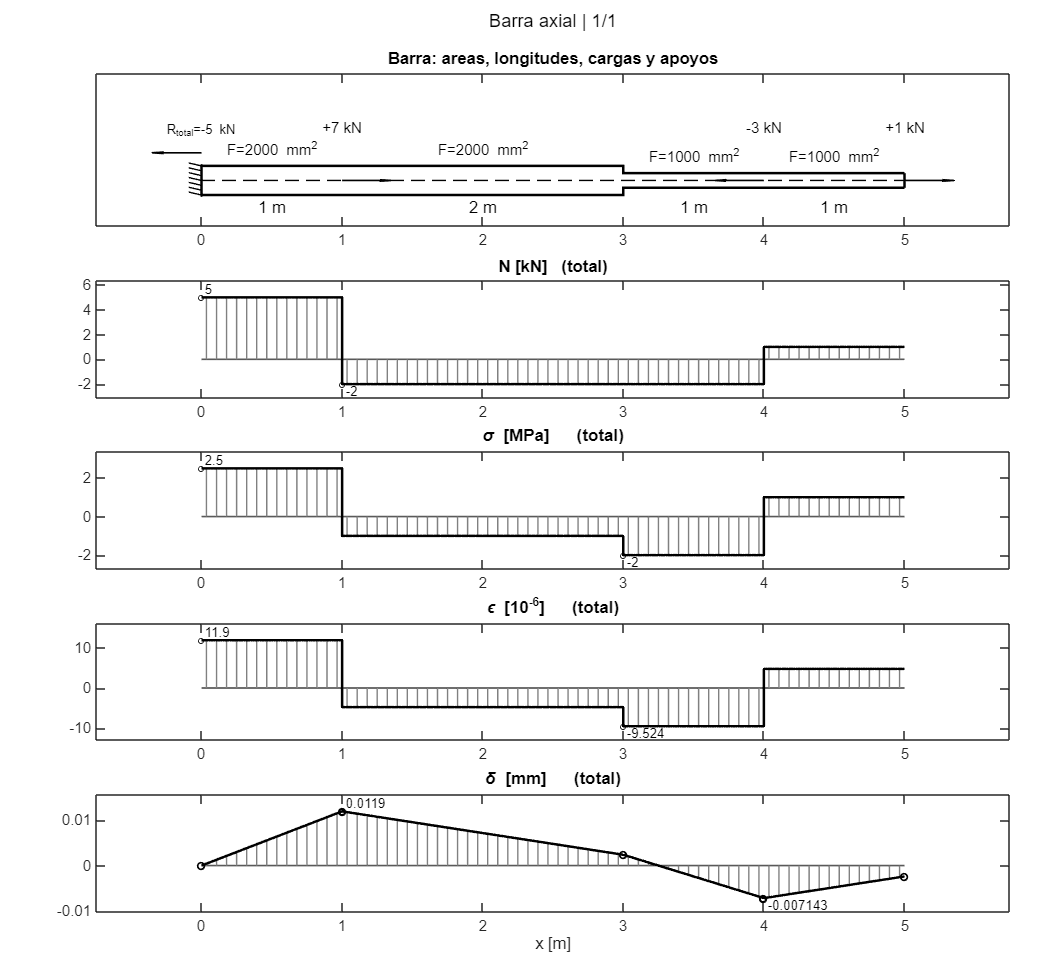

if compararCasos
    estudio=ae_casos(analisis,datos,casos,limiteDesplazamientoCasos);
    assert(isscalar(casoDetalle)&&ismember(casoDetalle,1:numel(estudio.soluciones)), ...
        'casoDetalle debe identificar un caso calculado.');
    solucion=estudio.soluciones{casoDetalle};
    disp(estudio.tabla);
else
    solucion=ae_resolver(analisis,datos);
end

solucion.identificacion=identificacion;

## 5. Memoria matemática del caso

La memoria muestra ecuaciones renderizadas y valores obtenidos de esta ejecución. Para barras axiales se presentan equilibrio, esfuerzo, tensión, deformación y desplazamiento por tramos. Para marcos se documenta el sistema matricial, sus condiciones y los campos de las barras elegidas. El eje local s comienza en el primer nodo de cada barra.

elementosMemoria contiene los índices de tramos, barras o puntos que deseas desarrollar. [] significa todos. En una estructura extensa, selecciona los elementos relevantes. maxFilasMatriz limita únicamente la presentación de matrices; no reduce el modelo calculado. Se conservan las matrices completas en solucion.resultado cuando el modelo las devuelve.

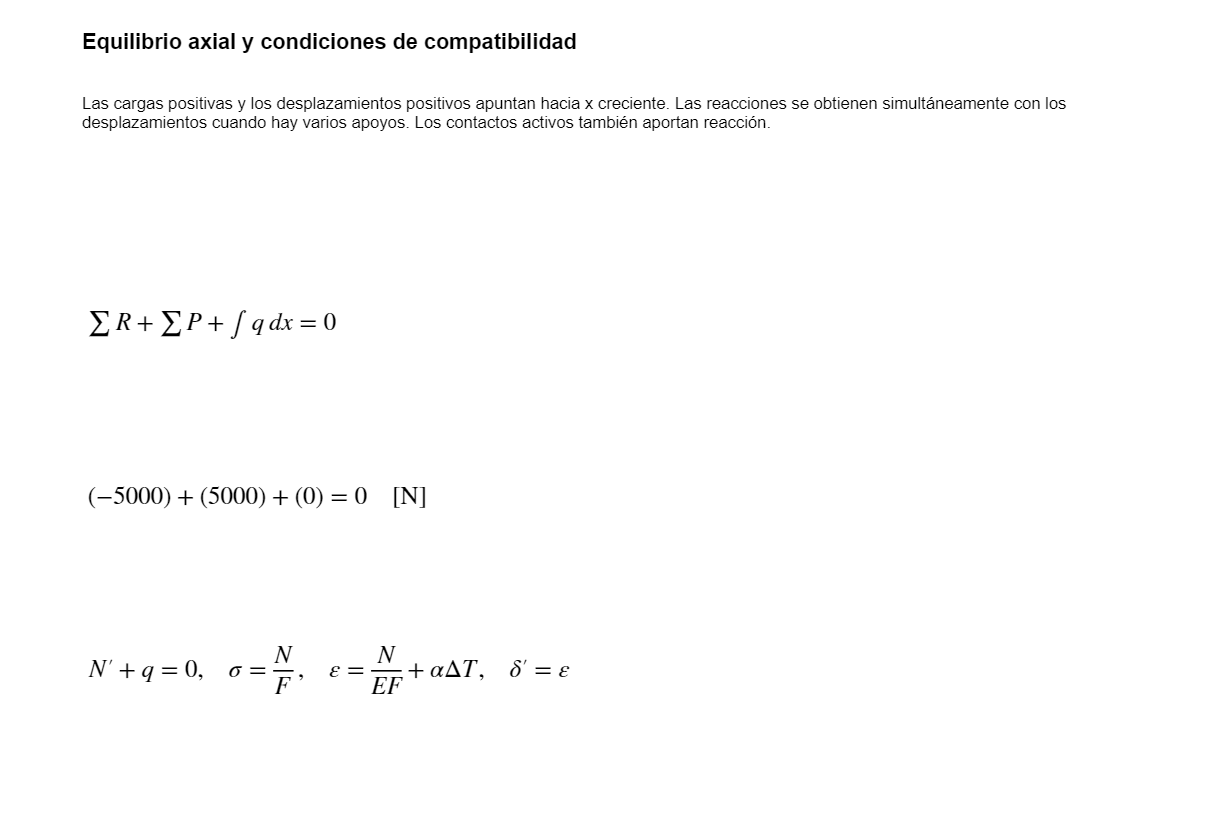

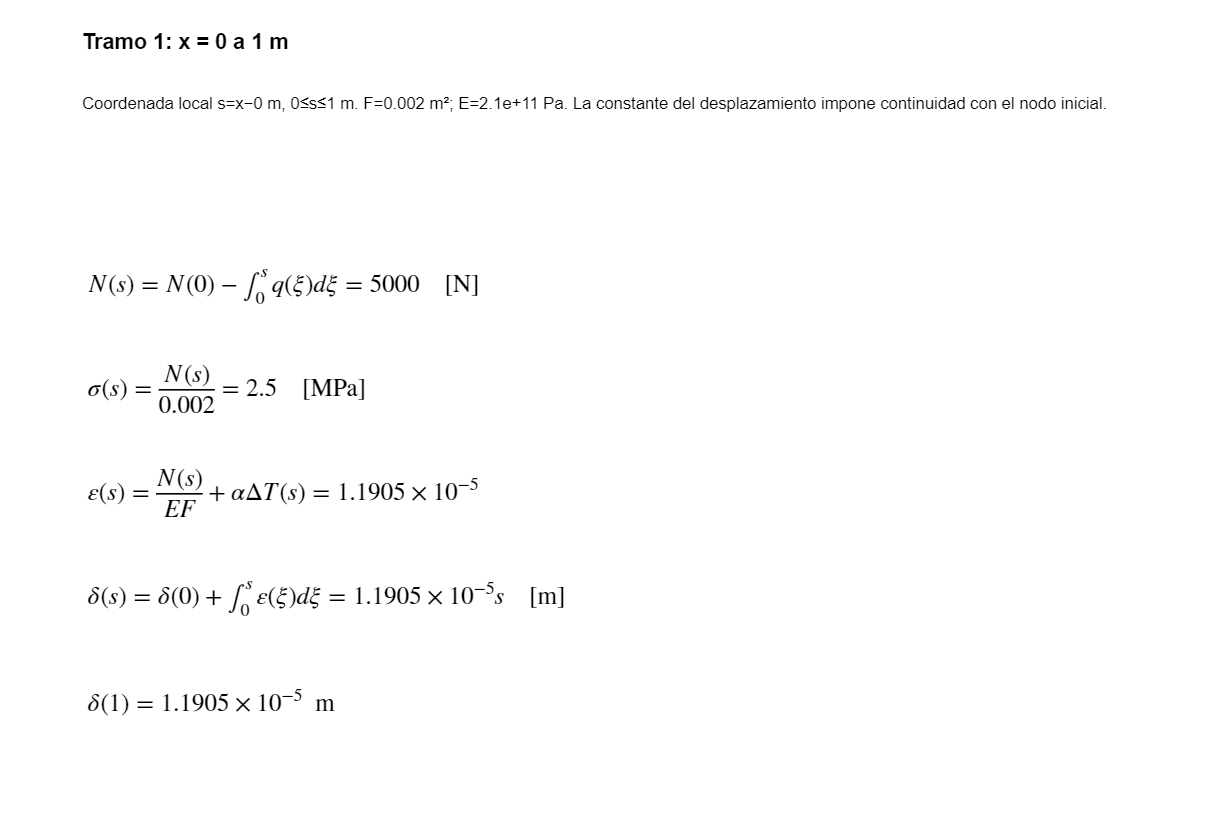

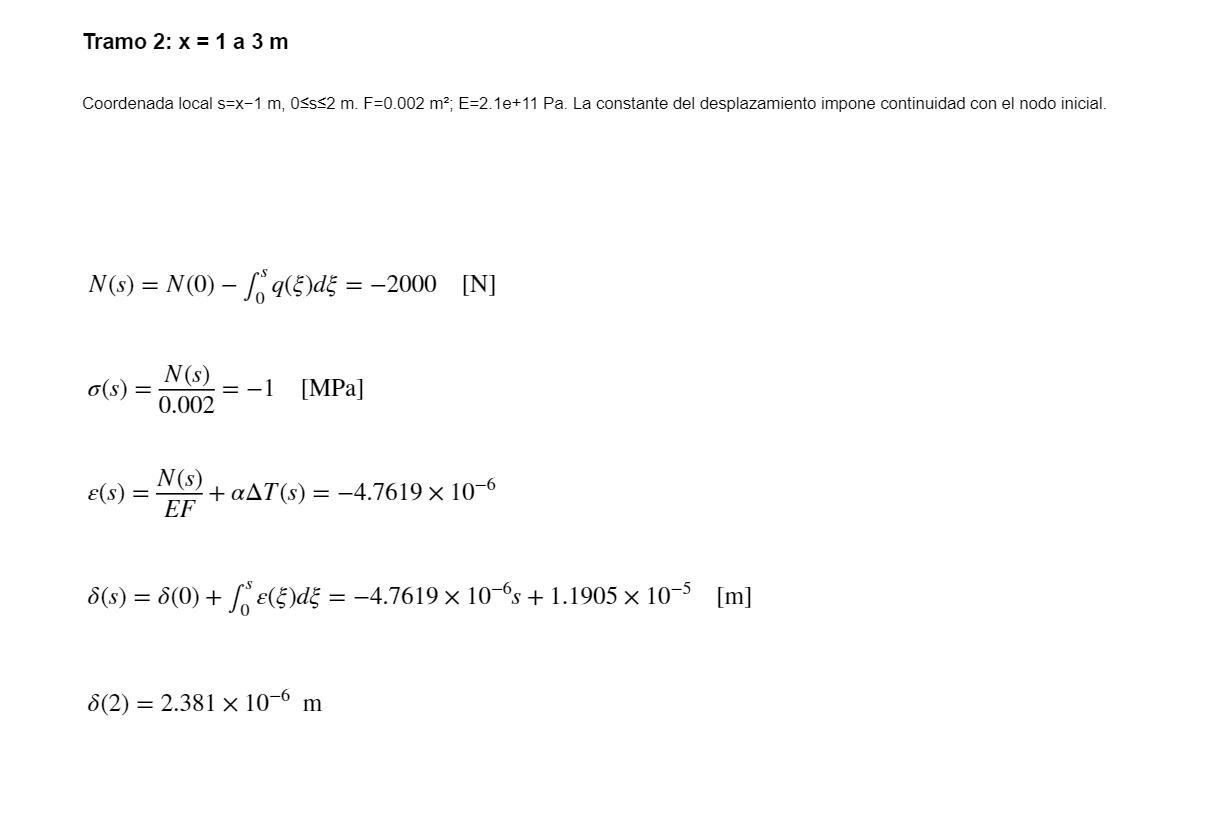

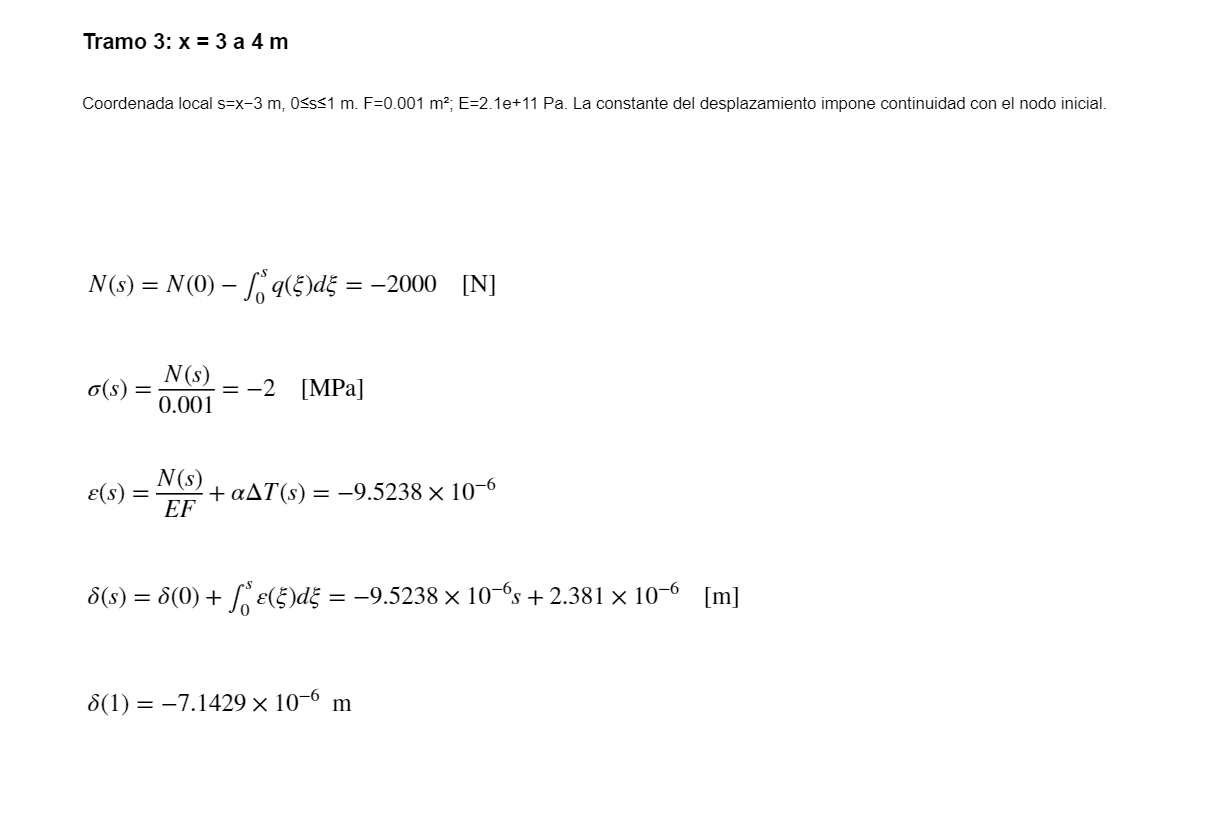

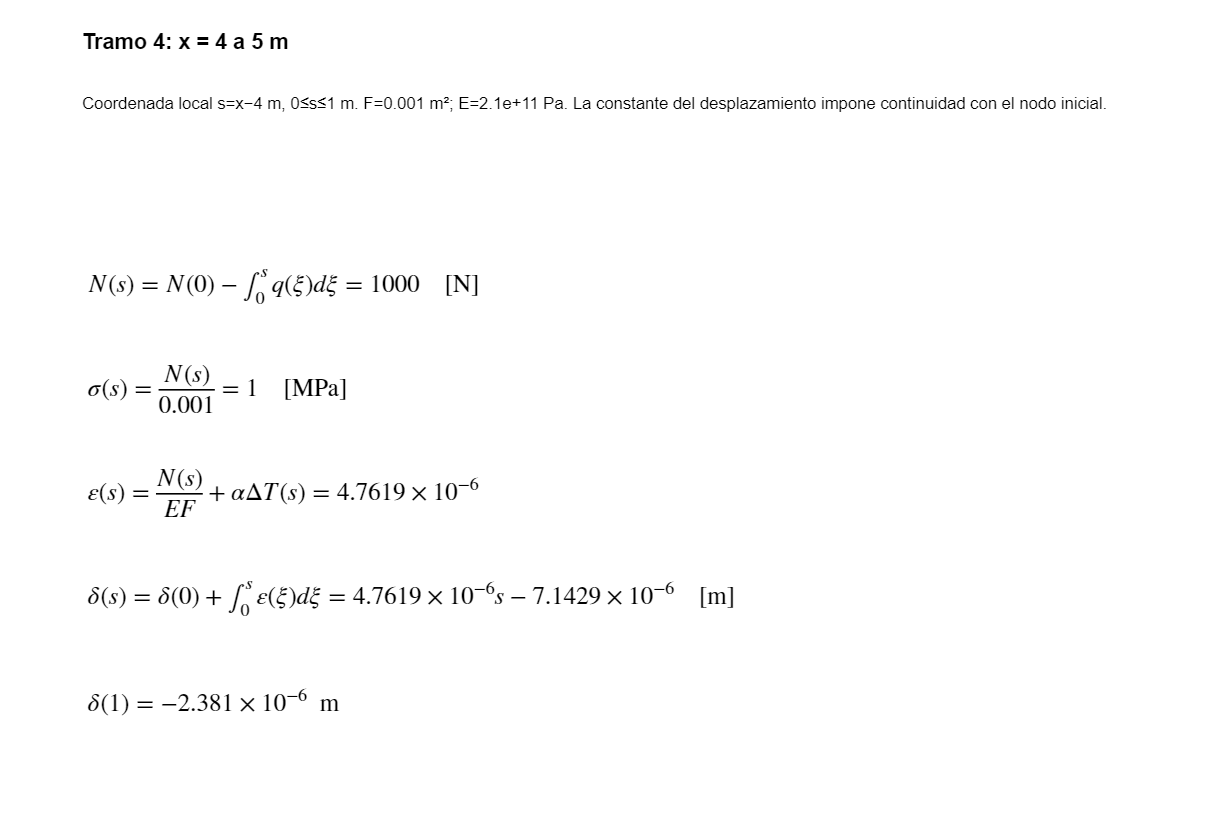

opcionesMemoria.elementos=[];
opcionesMemoria.maxFilasMatriz=4;
memoria=ae_memoria(solucion,opcionesMemoria);

## 6. Interpretación y comprobaciones

Lee el signo y la unidad de cada magnitud. N positivo representa tracción; los giros y momentos espaciales siguen la regla de la mano derecha. En marcos, cada barra tiene ejes locales propios. Las deformadas se amplifican para ver su forma y no representan a escala el desplazamiento real. Las epiuras se generan a partir del modelo elegido, con los esfuerzos que este puede transmitir.

disp(solucion.comprobaciones);

         Ejecucion: "Completada"
           Alcance: 'Barra recta axial, E y F constantes por tramo, pequeñas deformaciones, cargas y temperatura lineales por tramo, apoyos bilaterales y hasta ocho topes unilaterales. No comprueba pandeo.'
    Interpretacion: "Los controles verifican el modelo; revisa por separado su aplicabilidad fisica."
      ControlAxial: [1×1 struct]
       Resistencia: [1×1 struct]



disp("ANALISIS ESTRUCTURAL INTEGRADO: calculo completado.");

ANALISIS ESTRUCTURAL INTEGRADO: calculo completado.


Un resultado de resistencia requiere límites de material y un criterio apropiado. Un análisis de esfuerzos no incluye automáticamente fatiga, estabilidad, uniones o concentraciones locales. Para estudiar varios fenómenos conserva el resultado de cada ejecución con un nombre distinto y transfiere los esfuerzos mediante sus unidades y ejes. No se ejecutan indiscriminadamente dieciséis teorías sobre los mismos datos.

El estado Parcial identifica mecanismos pendientes dentro de la carga introducida: por ejemplo, cortante transversal de una sección general o interacción de compresión y cortante en una placa. Un margen positivo en los mecanismos calculados no cierra esas comprobaciones pendientes. La soldadura y las fijaciones se estudian como componentes de la trayectoria de cargas, con demandas obtenidas del conjunto.

## Preparación de un soporte con una masa montada

Para un estudio cuasiestático, el peso y la fuerza de inercia se pueden representar en el centro de masa. La fuerza equivalente es m(g−a), donde g y a son vectores en los mismos ejes globales; el traslado al nodo de aplicación añade el momento r×F. No suma de nuevo el peso si las cargas de entrada ya lo incluyen. Esta representación no calcula vibración, resonancia, movimiento del líquido ni fatiga de carretera.

La función ae_carga_masa recibe masa [kg], centro de masa [m], punto de traslado [m], aceleración de la base [m/s²] y gravedad [m/s²]. Por ejemplo, carga=ae_carga_masa(50,[0.2 0 0.3],[0 0 0],[0 0 0],[0 0 -9.81]) devuelve una fila [FX FY FZ MX MY MZ]. Esa fila se añade a datos.cargas junto al número de nodo del marco espacial; no se asigna automáticamente a una fijación.

## Referencia de uso

Consulta GUIA_ANALISIS_INTEGRADO.md para cambiar de familia, preparar un caso y repetir una comprobación. La memoria desarrolla las ecuaciones de los modelos implementados; no genera una demostración simbólica arbitraria de cualquier estructura o material.